# Center a molecule

Import a structure and center it

close all;
atom=import_atom('6x4MMT_x10y5z0.gro'); % A non-centered structure

Found .gro file
.gro file imported
Elapsed time is 0.239930 seconds.


composition = struct with fields:
     resnames: {'MMT'}
    nresidues: 1
       natoms: 960

Atom_types = 1×4 cell array
    'Al'    'H'    'O'    'Si'

Atom_numbers =     96    96   576   192

Box_dim =    31.1880   36.0600   10.0000

atom=center_atom(atom,Box_dim); % This will also replicate Box_dim

Center to box
centering along x
centering along y
centering along z


ans = -0.0050

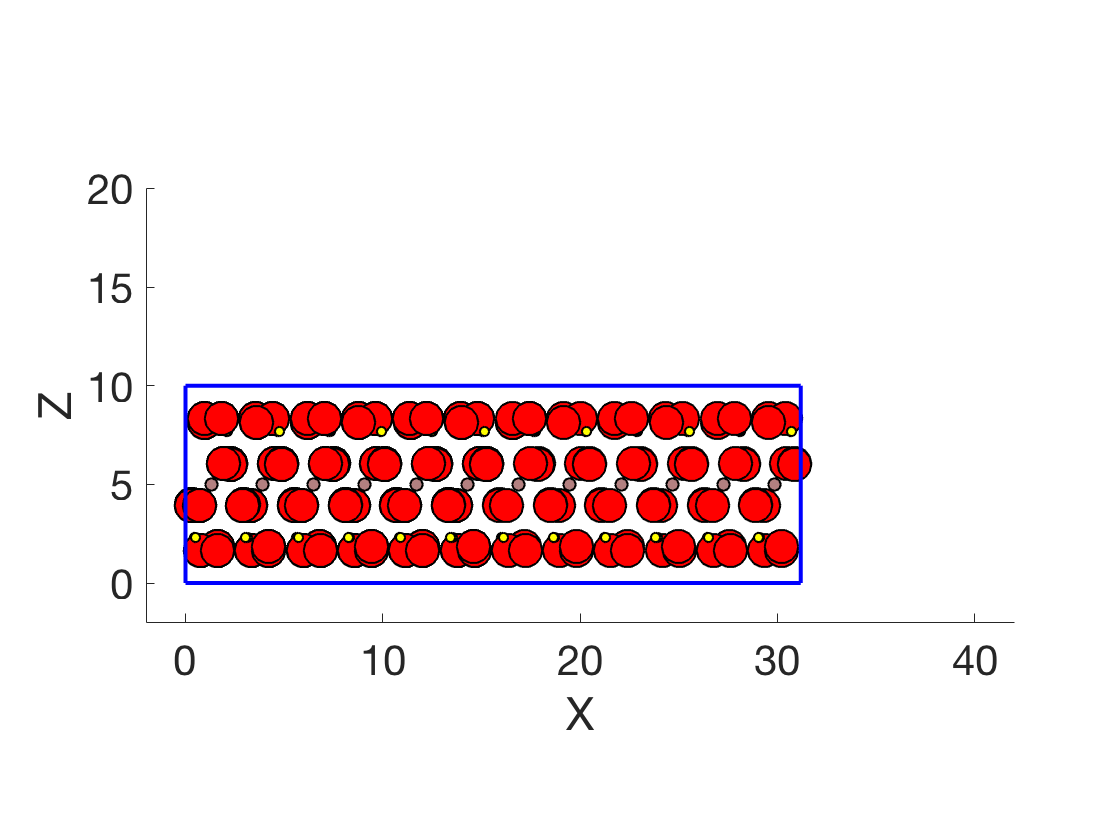

plot_atom(atom,Box_dim);

%vmd(atom,Box_dim)

We can also center with respect to a certain resname group (here `'MMT'`)

close all;
atom=import_atom('6x4MMT_x10y5z0.gro');

Found .gro file
.gro file imported
Elapsed time is 0.315666 seconds.


composition = struct with fields:
     resnames: {'MMT'}
    nresidues: 1
       natoms: 960

Atom_types = 1×4 cell array
    'Al'    'H'    'O'    'Si'

Atom_numbers =     96    96   576   192

Box_dim =    31.1880   36.0600   10.0000

atom=center_atom(atom,Box_dim,'MMT'); % Default 'all'

Center to box
centering along x
centering along y
centering along z


ans = -0.0050

plot_atom(atom,Box_dim);

%vmd(atom,Box_dim)

Or we can center with respect a certain x, y or z direction (here in the `'z'` direction)

close all;
atom=import_atom('6x4MMT_x10y5z0.gro');

Found .gro file
.gro file imported
Elapsed time is 0.267328 seconds.


composition = struct with fields:
     resnames: {'MMT'}
    nresidues: 1
       natoms: 960

Atom_types = 1×4 cell array
    'Al'    'H'    'O'    'Si'

Atom_numbers =     96    96   576   192

Box_dim =    31.1880   36.0600   10.0000

atom=center_atom(atom,Box_dim,'MMT','z'); % Default 'xyz'

Center to box
centering along z


ans = -0.0050

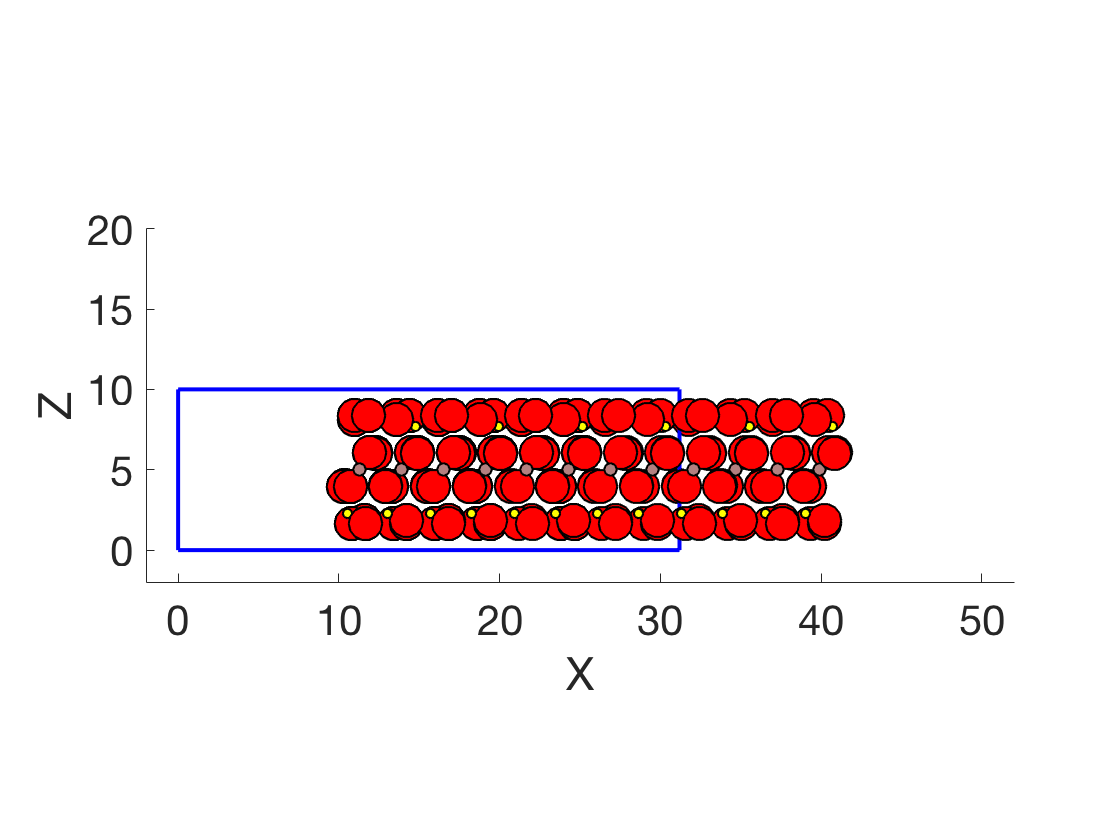

plot_atom(atom,Box_dim);

%vmd(atom,Box_dim)